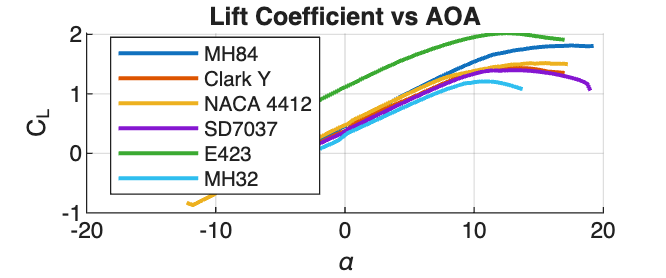

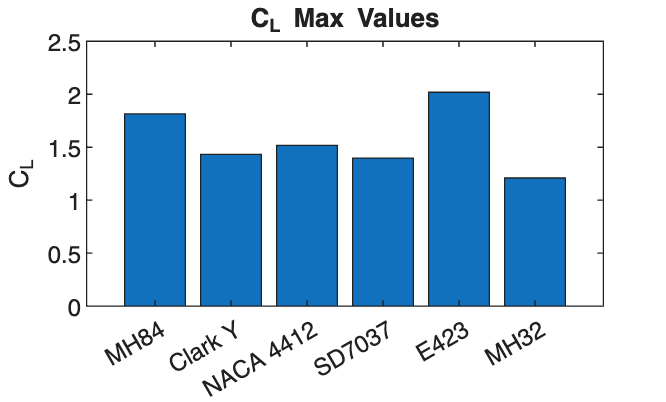

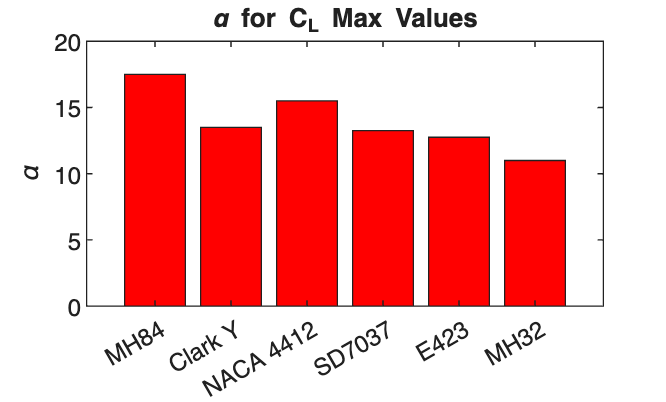

% Airfoils
files = {'mh84.csv','clarky.csv','naca4412.csv','sd7037.csv','e423.csv','mh32.csv'};
names = {'MH84','Clark Y','NACA 4412','SD7037','E423','MH32'};

% Storing alpha, CL, CD, CM, & E
airfoil = struct();
n = numel(files);
for i = 1:n
    addpath("data/")
    M = readmatrix(files{i});
    airfoil(i).name = names{i};
    airfoil(i).alpha = M(:,1);
    airfoil(i).CL = M(:,2);
    airfoil(i).CD = M(:,3);
    airfoil(i).CM = M(:,5);
    airfoil(i).E = M(:,2)./M(:,3);
end

plotmaxAirfoil(airfoil,n,'alpha','CL','\alpha','C_L','Lift Coefficient vs AOA',names);

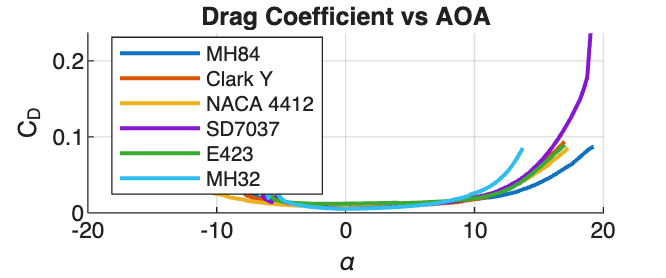

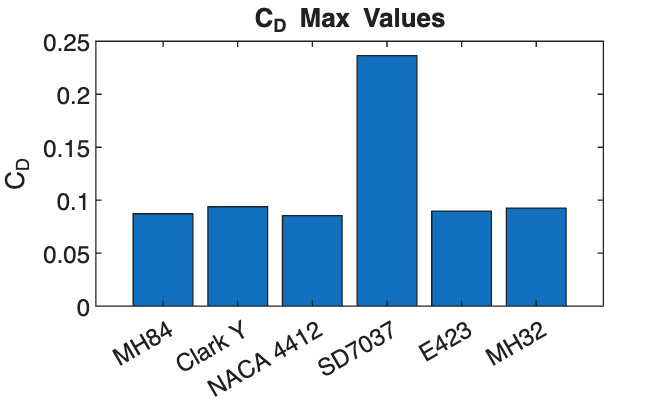

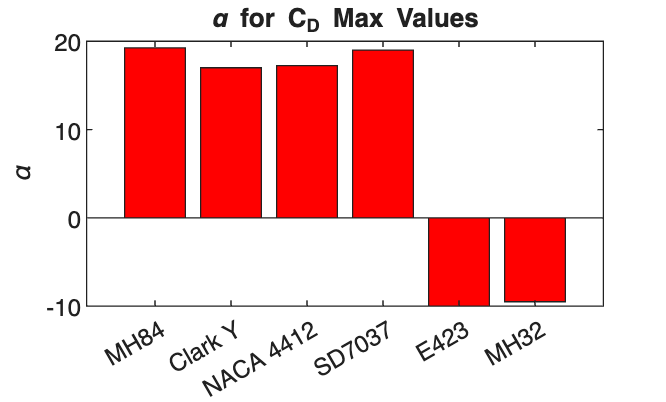

plotmaxAirfoil(airfoil,n,'alpha','CD','\alpha','C_D','Drag Coefficient vs AOA',names);

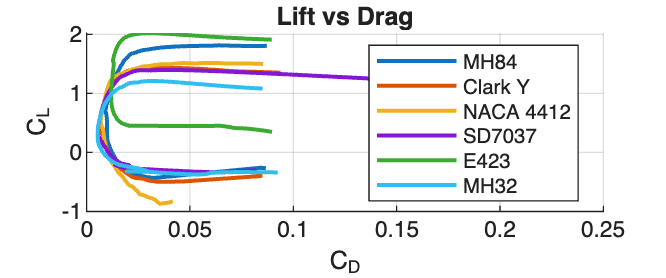

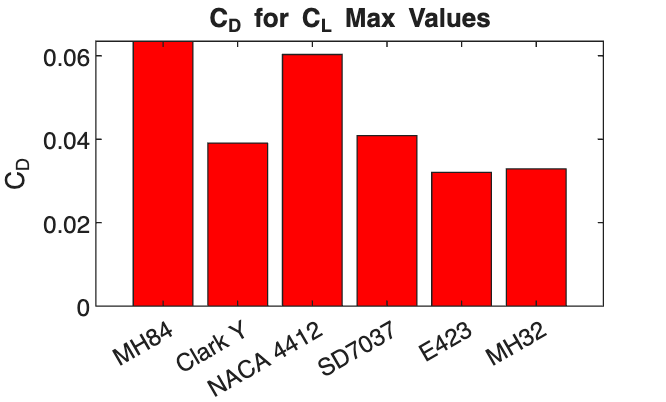

plotmaxAirfoil(airfoil,n,'CD','CL','C_D','C_L','Lift vs Drag',names);

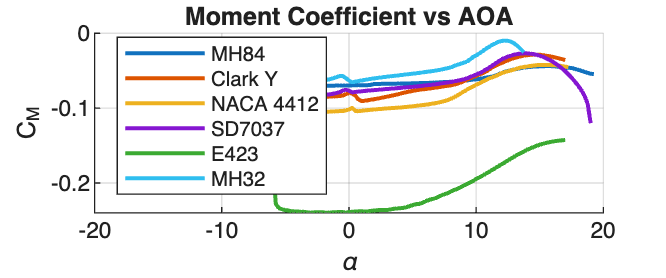

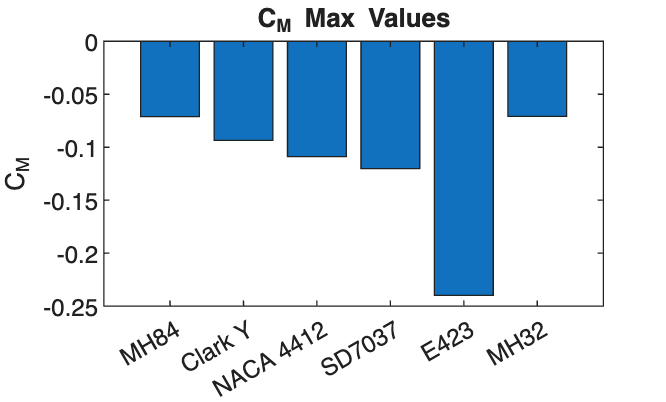

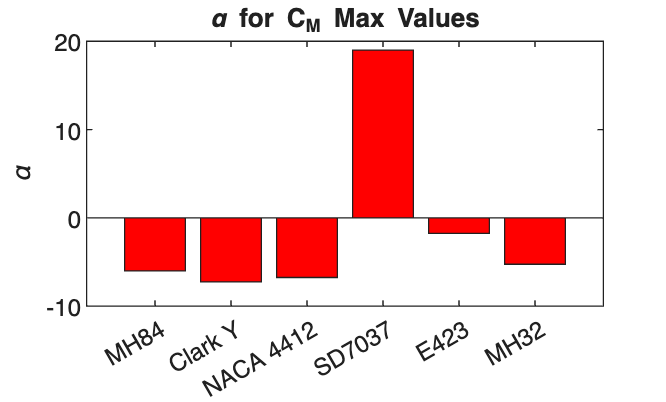

plotmaxAirfoil(airfoil,n,'alpha','CM','\alpha','C_M','Moment Coefficient vs AOA',names);

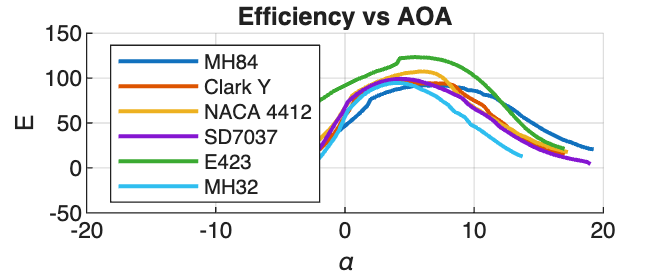

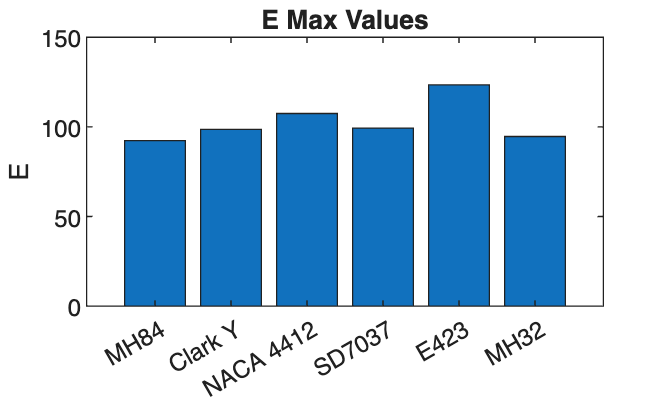

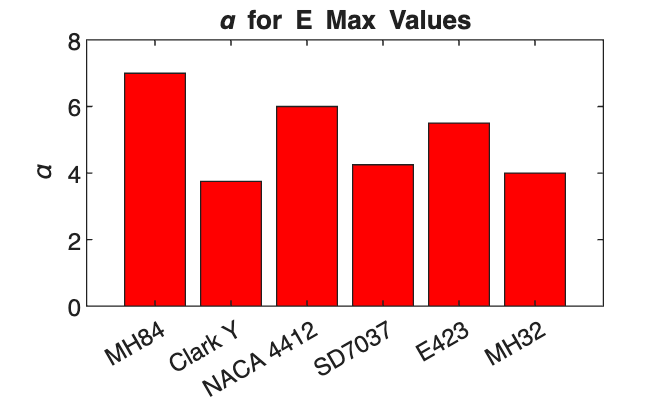

plotmaxAirfoil(airfoil,n,'alpha','E','\alpha','E','Efficiency vs AOA',names);

% ~~~~~~~~~Selection~~~~~~~~~ %
ref1 = '<a href = "https://www.walshmedicalmedia.com/open-access/optimum-slat-and-flap-configuration-for-maximizing-lift-on-naca4412-airfoil-at-various-angle-of-attack-using-xfoil-at-a-.pdf">NACA-4412 Optimum Slat & Flap Paper</a>';
ref2 = '<a href = "https://koreascience.kr/article/JAKO200928842526583.pdf">NACA-4412 Flap CFD Study</a>';
disp(ref1)

<a href = "https://www.walshmedicalmedia.com/open-access/optimum-slat-and-flap-configuration-for-maximizing-lift-on-naca4412-airfoil-at-various-angle-of-attack-using-xfoil-at-a-.pdf">NACA-4412 Optimum Slat & Flap Paper</a>


disp(ref2)

<a href = "https://koreascience.kr/article/JAKO200928842526583.pdf">NACA-4412 Flap CFD Study</a>


disp("CLmaxTO = 2 with flaps for NACA-4412 @ 6deg AOA (ref2)")

CLmaxTO = 2 with flaps for NACA-4412 @ 6deg AOA (ref2)


CLcruiseIdx = 3 == airfoil(3).alpha;
CLcruise = airfoil(3).CL(CLcruiseIdx);
dispstr = "CL Cruise = " + CLcruise + " (@ max eff. for NACA-4412";
disp(dispstr)

CL Cruise = 0.8073 (@ max eff. for NACA-4412


% ~~~~~~~~~Functions~~~~~~~~~ %
function plotmaxAirfoil(airfoil, n, xField, yField, xLabel, yLabel, titleStr, names)
    maxMat = ones(2,n);
    figure(Position=[100 100 1200 500])
    hold on
    for i = 1:n
        x = airfoil(i).(xField);
        y = airfoil(i).(yField);
        plot(x, y,LineWidth=1.5)
        
        if yField == "CM"
            maxval = min(airfoil(i).(yField));
        else
            maxval = max(airfoil(i).(yField));
        end
        idx = maxval == airfoil(i).(yField);
        maxMat(2,i) = maxval;
        maxMat(1,i) = max(airfoil(i).(xField)(idx));
    end
    hold off
    xlabel(xLabel)
    ylabel(yLabel)
    title(titleStr)
    legend(names,Location="best")
    grid on
    
    figure
    y = maxMat(2,:);
    bar(names,y)
    ylabel(yLabel)
    titleStr = yLabel + " Max Values";
    title(titleStr)
    figure
    x = maxMat(1,:);
    bar(names,x,"r")
    ylabel(xLabel)
    titleStr = xLabel + " for " + yLabel +" Max Values";
    title(titleStr)
   
end